#  Reglas derivadas para combinaciones de funciones 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

 Como se presenta en [Reglas derivadas para potencias](matlab:open('./PowerRules.mlx')) y [Reglas derivadas para funciones trascendentales](matlab:open('./TranscendentalsRules.mlx'))

** Potencia & Reglas de linealidad **                               ** Reglas trascendentales **            

$\frac{d}{dx}\left[x^n\right] = nx^{n-1}$ para constante $n$         $\frac{d}{dx}\left[\sin(x)\right] = \cos(x)$             $\frac{d}{dx}\left[e^x\right] = e^x$

$\frac{d}{dx}\left[cf(x)\right] = c\frac{df}{dx}$ para constante $c$         $\frac{d}{dx}\left[\cos(x)\right] = -\sin(x)$     $\frac{d}{dx}\left[\ln(x)\right] = \frac{1}{x}$      


$$\frac{d}{dx}\left[f(x)+g(x)\right] = \frac{df}{dx}+\frac{dg}{dx}$$
                                                                                                              

Sin embargo, con la excepción de los polinomios, la mayoría de las funciones comunes siguen siendo falta en esta lista de reglas. Este guión presentará las dos reglas fundamentales restantes para calcular las derivadas de combinaciones de funciones y presentará aplicaciones de estas reglas a una variedad de situaciones matemáticas y del mundo real. 

** Antes de comenzar: **

 Este script en vivo está diseñado para usarse con el código oculto. En la pestaña ** Ver ** de la barra de herramientas de MATLAB, en la sección ** Ver **, seleccione ** Ocultar código **. Alternativamente, seleccione ** Ocultar código ** usando el ícono   en la parte superior derecha del panel Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesita más instrucción, considere realizar [Rampa de entrada de MATLAB](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB. 

 Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se agotan. 

##  Regla de la cadena 

 Considere dos funciones $y = f(x)$ y $z = g(x)$. Después de formar una nueva función $y_2 = f(z) = f(g(x))$ componiendo $(f \circ g)(x)$ , ¿cuál es la derivada? 

###  Derivación de la regla de la cadena 

 La respuesta depende de ser un poco más específico. ¿Cuál es la variable independiente en la pregunta sobre la derivada de una función creada al componer dos funciones? Si es $z$ no hay nada nuevo sucediendo: 


$$\frac{dy_2}{dz} = \frac{d}{dz}\left[f(z)\right] = \frac{df}{dz} = f'(z)$$


 Sin embargo, si es $x$ , entonces: 


$$\frac{dy_2}{dx} = \frac{d}{dx}\left[(f\circ g)(x)\right] = \lim_{\Delta x \to 0} \frac{f(g(x+\Delta x))-f(g(x))}{\Delta x}$$
                                                            

                                   
$$=\lim_{\Delta x\to 0} \left(\frac{f((g(x+\Delta x)-g(x))+g(x))-f(g(x))}{g(x+\Delta x)-g(x)}\right)\left(\frac{g(x+\Delta x)-g(x)}{\Delta x}\right)$$


 Sea $\Delta g = g(x+\Delta x) -g(x)$ el cambio en el valor $g$ en función del cambio en el valor $x$ $\Delta x$. Luego: 


$$\frac{dy_2}{dx} =\lim_{\Delta x \to 0}\left(\frac{f(g+\Delta g)-f(g)}{\Delta g}\right)\left(\frac{g(x+\Delta x)-g(x)}{\Delta x}\right)$$
    

 Tenga en cuenta que $\lim_{\Delta x \to 0} \Delta g = \lim_{\Delta x \to 0} g(x+\Delta x)-g(x) = 0$ , entonces: 

   
$$\frac{dy_2}{dx} = \left(\lim_{\Delta g \to 0} \frac{f(g+\Delta g)-f(g)}{\Delta g}\right)\left(\lim_{\Delta x \to 0}\frac{g(x+\Delta x)-g(x)}{\Delta x}\right)$$



$$=\frac{df}{dg}\cdot \frac{dg}{dx}$$
                                                             

                          
$$=f'(g)\cdot g'(x) = f'(g(x))\cdot g'(x)$$
                                                  

 Visualice la regla de la cadena configurando las funciones `f(x)` y `g(x)` así como eligiendo los límites superior e inferior para el dominio: 

syms x                         % Crear una variable simbólica x
figure 
f(x) =  x^3;   % Función definida por el usuario f(x), por defecto x^3
g(x) =  -.4*x+2;   % Función definida por el usuario g(x), por defecto -.4*x+2
a = -5;      % Valor definido por el usuario de a, por defecto -5
b = 5;      % Valor definido por el usuario de b, por defecto 5
if a < b                       % Verifique si a < b para asegurarse de que se siguieron las instrucciones
    bds = [a, b];
else                           % Si ~(a<b), establezca los límites predeterminados y advierta al usuario
    bds = [-5, 5];
    disp("Tu límite inferior no es menor que tu límite superior. Usando límites predeterminados de [-5, 5].")
end
                     % Ejecute esta sección
% Configure y muestre las funciones definidas por el usuario al usuario
fx = f(x);                     % Configurar la función para mostrar su valor
gx = g(x);                     % Configurar la función para mostrar su valor
disp("Las funciones originales son:")
displayFormula("f(x) = fx")
displayFormula("g(x) = gx")
% Luego configure y muestre la función combinada
disp("Combinando las funciones a través de la composición:")
fg = f(g(x));                    % Configurar la función para mostrar su valor
displayFormula("f(g(x)) = fg")   % Mostrar el resultado compuesto
disp("Por lo tanto,")
fg0 = f(g(bds(1)));              % Configurar la función para mostrar su valor
g0 = g(bds(1));                  % Configurar la función para mostrar su valor
a0 = bds(1);                     % Configurar el punto para mostrar su valor
displayFormula("g(a0) = g0")       % Mostrar el resultado de evaluar g() en un punto
disp("y")
displayFormula("f(g(a0)) = fg0") % Mostrar el resultado de evaluar f(g()) en un punto
ShowChainRule(@(x)f(x),@(x)g(x),bds,"f","g");

 Luego anime este gráfico observando cómo la derivada de la función combinada `f(g(x))` se relaciona con las derivadas de cada subcomponente `f(g)` y `g(x)`. 

                  % Ejecute esta sección
if ~exist("f","var") || ~exist("g","var") || ~exist("bds","var")
    % Si la sección anterior no se ha ejecutado, configure los valores predeterminados para las variables requeridas
    syms x
    f(x) = x^3;
    g(x) = -.4*x+2;
    bds = [-5 5];
end
[fh,gh,bds,gMin,gMax,cT,pf,pfT,pfg,pfgT,pg,pgT] = ShowChainRule(@(x)f(x),@(x)g(x),bds,"f","g");
AnimateChainRule(fh,gh,bds,gMin,gMax,cT,pf,pfT,pfg,pfgT,pg,pgT);
% AnimateChainRule is defined in Local Helper Functions
% AnimateChainRule loops over 100 values in bds to show how the derivative
% of the composite function is the product of the derivatives df/dg and
% dg/dx, such as when both left-hand tangents have negative slope but the
% right-hand tangent has a positive slope, etc.

###  Aplicación: Péndulo 

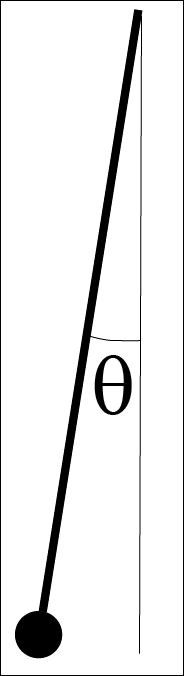

 Se puede demostrar que para ángulos pequeños, el ángulo en función del tiempo para un péndulo es: 


$$\theta(t) = \theta_0 \enspace \cos \left(t\sqrt{\frac{g}{L}} \right)$$


 donde $g$ es la aceleración debida a la gravedad, $L$ es la longitud del péndulo, y $\theta_0$ es el ángulo inicial del péndulo. La velocidad angular del péndulo, $\omega(t)$, se puede encontrar tomando la derivada de $\theta(t)$ con respecto a $t$. 

** Ejercicio 1 **. 

-  Encuentra la expresión para la velocidad angular $\frac{d\theta}{dt} = \omega(t)$. 

-  Según tu conocimiento sobre un péndulo, ¿dónde esperarías que la velocidad angular fuera cero? Después de pensar en esto, usa la expresión que acabas de encontrar para $\omega(t)$ y encuentra un momento (distinto de $t = 0$) en el que el péndulo esté en reposo. En este momento, ¿cuál es el valor de $\theta(t)$? ¿Está donde esperarías que estuviera? 

-  De manera similar, la aceleración angular, $\alpha(t)$ , del péndulo se puede encontrar como la derivada de la velocidad angular con respecto al tiempo. Encuentre la expresión para la aceleración angular $\frac{d^2\theta}{dt^2}=\alpha(t)$. 

SelectedPendulumAnswers= false;
ShowPendulumAnswers(SelectedPendulumAnswers);

###  Aplicación: Tarifas relacionadas 

 Considere un disco de vinilo clásico que gira a 45 rotaciones por minuto en su tocadiscos. 

% Este código dibuja una espiral negra apretada con una espiral roja apretada en el interior para
% producir la idea de un disco de vinilo.
figure
recFig = DrawRecord;      % DrawRecord está en funciones auxiliares locales
 

 Esta velocidad de rotación significa que $\frac{d\theta}{dt}$ es una constante. De hecho, 45 rotaciones por minuto significa 

$\frac{d\theta}{dt}$ = $\left(45\frac{\text{rotaciones}}{\text{minuto}}\right)\left(2\pi \text{ radianes }\right)\left(\frac{1 \text{ minuto}}{60 \text{ secondo}}\right)$ = $\frac{3\pi}{2}$ radianes por segundo. 

 Coloca una aguja cerca del borde exterior del disco con $\theta = 0$ radianes y sigue su trayectoria a lo largo de $r(\theta) = \left(7-\frac{7}{80}\theta\right)$ pulgadas y obsérvala a medida que avanza hacia el borde interior. Este camino está trazado por la estrella amarilla en el gráfico siguiente. 

thetaN = linspace(0,23*pi,184);
if exist("recFig","var")                     % Comprobar si la cifra récord se ha generado localmente
    hold on
    pN = plot(recFig.CurrentAxes,0,7,"y*");  % Si es así, traza un nuevo punto encima de la misma figura del registro.
    hold off
elseif ~exist("recFigWPt","var")             % Compruebe si la animación de grabación se ha ejecutado localmente
    figure
    recFigWPt = DrawRecord;                  % En caso contrario, generar una cifra local del registro.
    hold on
    pN = plot(0,7,"y*");                     % Luego agregue el punto encima de la cifra del registro.
    hold off
end
for k = 1:184                                % Animar la posición de la aguja mientras se reproduce el disco.
    pN.XData = (7-7/80*thetaN(k))*cos(thetaN(k));
    pN.YData = (7-7/80*thetaN(k))*sin(thetaN(k));
    drawnow
end
hold off
 

 La aguja, representada por la estrella amarilla, se mueve hacia el centro del disco a medida que avanza el tiempo. Utilice el cálculo para calcular la velocidad a la que $r$, la distancia desde la aguja al centro, cambia después de 45 segundos de tiempo de reproducción. 

** Ejercicio 2 **. 

-  ¿Cuál es el ángulo, $\theta$ , después de 45 segundos de juego? Por favor dé su respuesta en radianes. 

theta = 0;         % Solución de entrada del usuario para theta (45 segundos) en radianes

 2. ¿Cuál es la velocidad angular, $\frac{dr}{d\theta}$ , después de 45 segundos de tiempo de reproducción? Por favor dé su respuesta en pulgadas por radianes. 

AngularSpeed = 0;  % Solución de entrada del usuario para dr/dtheta en pulgadas/radianes

 3. ¿Cuál es la velocidad lineal, $\frac{dr}{dt}$ , después de 45 segundos de juego? Por favor dé su respuesta en pulgadas por segundo. 

LinearSpeed = 0;   % Solución de entrada del usuario para dr/dt en pulgadas/segundo
CheckSpeed(theta,AngularSpeed,LinearSpeed);   % CheckSpeed ��se define en Funciones auxiliares locales
% CheckSpeed compares the input solutions of theta, AngularSpeed, and
% LinearSpeed to their correct values and displays feedback. When correct,
% the feedback includes the solution with appropriate units
                           % Ejecute esta sección

###  Problemas de reglas de cadena de práctica 

 Generar problemas de práctica aleatorios. Primero, haga clic en ** Inicializar valores ** una vez para comenzar. Luego, cada vez que desee un nuevo problema, haga clic en el botón ** Generar problema ** cada vez para crear un nuevo problema. Después de resolver el problema, ingrese su solución como código MATLAB y haga clic en el botón ** Comprobar respuesta **. 

  ** Consejo profesional **. La variable que uses en la solución es importante, al igual que el uso apropiado de paréntesis y operadores de multiplicación. La sintaxis de MATLAB es `exp(7*t^(2/3))` para $e^{7t^{2/3}}$ , `sin(7*cos(4*r-6))` para $\sin(7\cos(4r-6))$ y `log(z/2)` para $\ln\left(\frac{z}{2}\right)$. 

% Borrar variables
clear MyFun VarChoice MyAnswer TotPRProbs TotCRProbs TotMDProbs                        
syms t r x z                         % Declarar variables simbólicas
VarOpts = [t r x z];                 % Definir la lista de variables a utilizar en los problemas.
ErrorCount = 0;                      % Inicializar un recuento de errores
TotCRProbs = 0;                      % Inicializar un recuento del total de problemas intentados
TotAttempts = 0;                     % Inicializar un recuento del total de soluciones ofrecidas
AdjustCount = 0;                     % Conservar los recuentos si el usuario vuelve a enviar una solución
LastFive = zeros(1,5);               % Inicializar una matriz para registrar los últimos cinco resultados de la solución
                        % Ejecute esta sección
disp("Valores inicializados para la práctica de la Regla de la Cadena.")

 ___________________________________________________________ 

 Genera un problema de regla en cadena: 

% Compruebe si la sección anterior se ha ejecutado
% Si no, proporcione ing. Si es así genera un problema.
if ~exist("TotCRProbs","var")
    warning("Debes inicializar los valores antes de poder generar un problema.")
else
    [MyFun,VarChoice] = GenProbType(VarOpts,3);  % GenProbType está definido en Funciones auxiliares locales
    % GenProbType configura una variable y genera una función aleatoria
    TotCRProbs = TotCRProbs+1;               % Aumentar el recuento total de problemas intentados.
end
                       % Ejecute esta sección 

MyAnswer = r;     % Solución definida por el usuario, valor predeterminado t
TotAttempts = TotAttempts + 1;       % Recuento de actualizaciones del total de intentos de solución
[LastFive,ErrorCount,TotAttempts,AdjustCount] = ResubmissionCheck(TotAttempts,TotCRProbs,AdjustCount,MyFun,VarChoice,MyAnswer,3,ErrorCount,LastFive);
% ResubmissionCheck is defined in Local Helper Functions
% ResubmissionCheck records the attempt and provides appropriate feedback
                          % Ejecute esta sección

 Una vez que hayas completado suficiente práctica, realiza un seguimiento de los resultados generales de tu práctica aquí: 

                        % Ejecute esta sección
AnalyzeResults(TotCRProbs,ErrorCount,TotAttempts,AdjustCount,LastFive)
% AnalyzeResults is defined in Local Helper Functions
% Compute the percentage of initially correct solutions out of the total
% problems attempted, subsequent attempts are not scored

####  Aplicación de práctica 

 Si prefieres practicar en la aplicación Calculus Flashcards, puedes comenzar hágalo haciendo clic en la imagen a continuación o haciendo clic en el botón Ejecutar la aplicación Calclus Flashcards. Debes configurarlo en "Regla de la cadena" en la sección Derivados. La aplicación se abrirá en una nueva ventana. 

[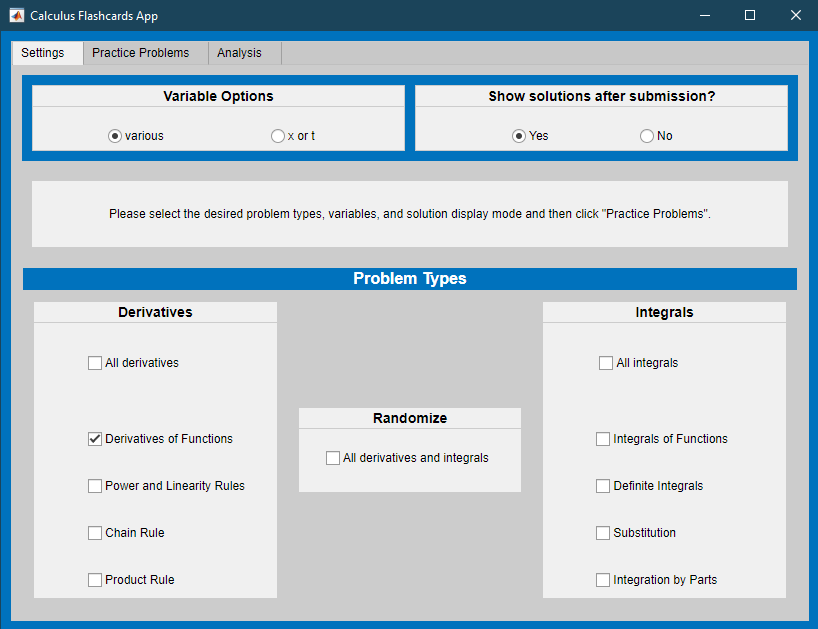](matlab: CalculusFlashcards)

 
run("TarjetasCalculo")

##  Regla del producto 

syms x                                   % Crear una variable simbólica
f = symfun(3*x+1,x);      % Función simbólica definida por el usuario, el valor predeterminado es 3*x+1
g = symfun(2*x^2-x+2,x);      % Función simbólica definida por el usuario, el valor predeterminado es 2*x^2-x+2
pt = 3;         % Valor de pt seleccionado por el usuario, el valor predeterminado es 3
h = 0.05;         % Tamaño de paso h seleccionado por el usuario, el valor predeterminado es 0,05
                        % Ejecute esta sección with options selected by the user

 Seleccione las funciones deseadas usando las casillas de verificación. `Show animation` recorre las tres etiquetas individuales y cierra con todas las etiquetas puestas. `Show axes` permite investigaciones explícitas de la escala de cada componente proporcionando etiquetas de eje. 

ShowAnimation = false; ShowAxes = true;

 Para centrarse en uno o dos componentes en particular sin la animación, seleccione la casilla de verificación correspondiente. 

ShowFG = false ; ShowChange = false; Showdfdg = false;
% Si no hay casillas de verificación seleccionadas, muestre un diagrama simple de la regla del producto.
if ~any([ShowAnimation ShowFG ShowChange Showdfdg])
    try
    ShowProductRule(prAx,f,g,pt,h,cols,ShowAxes);
    catch
        [prAx,cols,bkcol] = ShowProductRuleBasic(f,g,pt,h);
        ShowProductRule(prAx,f,g,pt,h,cols,ShowAxes);
    end
    % ShowProductRule está definido en funciones auxiliares locales
    % ShowProductRule takes two functions, a point, a step size, a set of
    %     colors, and a flag indicating whether to show the axes of the graph
    %     It generates an image consisting of four colored rectangles:
    %     The first is col1 and represents f*g
    %     The second and third are col3 and represent f*dg and g*df
    %     The fourth is col2 and represents dg*df
end
% Si se selecciona ShowAnimation, anima la figura.
if ShowAnimation
    if any([ShowFG ShowChange Showdfdg])
        disp("Cuando la animación está configurada para ejecutarse, las selecciones individuales son ignoradas por el script.")
        disp("Para enfocarse en selecciones individuales, por favor desmarque la casilla 'Mostrar animación'.")
    end
    try
        AnimateProductRule(prAx,f,g,pt,h,cols,bkcol,ShowAxes) %#ok<*UNRCH>
    catch
        ShowProductRule(prAx,f,g,pt,h,cols,ShowAxes);
        AnimateProductRule(prAx,f,g,pt,h,cols,bkcol,ShowAxes) %#ok<*UNRCH>
    end
    % AnimateProductRule is defined in Local Helper Functions
    % AnimateProductRule shows the basic product rule visualization and each
    % annotated component for a short time, then finishes with the fully
    % annotated plot
else
    % If any of the annotation boxes are selected, first generate the product
    % rule visualization, then annotate as requested
    if any([ShowFG ShowChange Showdfdg])
        try 
            ShowProductRule(prAx,f,g,pt,h,cols,ShowAxes)
        catch
            [prAx,cols,bkcol] = ShowProductRuleBasic(f,g,pt,h);
            ShowProductRule(prAx,f,g,pt,h,cols,ShowAxes);
        end
        % ShowProductRule está definido en funciones auxiliares locales
        % ShowProductRule takes two functions, a point, a step size, a set of
        %     colors, and a flag indicating whether to show the axes of the graph
        %     It generates an image consisting of four colored rectangles:
        %     The first is col1 and represents f*g
        %     The second and third are col3 and represent f*dg and g*df
        %     The fourth is col2 and represents dg*df
    end
    % Anotar con Área = f(x)*g(x)
    if ShowFG && ~any([ShowChange Showdfdg])
        AnnProdfg(f,g,pt,h,0)
    elseif ShowFG
        AnnProdfg(f,g,pt,h,1)
    end
    % Anotar con f(x)*dg + g(x)*df
    if ShowChange
        AnnProdChange(f,g,pt,h,cols{3},bkcol)
    end
    % Anotar con df*dg
    if Showdfdg
        AnnProddfdg(f,g,pt,h,cols{2},bkcol)
    end
end

###  Practicar problemas de reglas de productos 

 Generar problemas de práctica aleatorios. Primero, haga clic en ** Inicializar valores ** una vez para comenzar. Luego, cada vez que desee un nuevo problema, haga clic en el botón ** Generar problema ** cada vez para crear un nuevo problema. Después de resolver el problema, ingrese su solución como código MATLAB y haga clic en el botón ** Comprobar respuesta **. 

  ** Consejo profesional **. La variable que uses en la solución es importante, al igual que el uso apropiado de paréntesis y operadores de multiplicación. La sintaxis de MATLAB es `exp(7*t^(2/3))` para $e^{7t^{2/3}}$ , `sin(7*cos(4*r-6))` para $\sin(7\cos(4r-6))$ y `log(z/2)` para $\ln\left(\frac{z}{2}\right)$. 

% Borrar variables
clear MyFun VarChoice MyAnswer TotPRProbs TotCRProbs TotMDProbs
syms t r x z                         % Declarar variables simbólicas
VarOpts = [t r x z];                 % Definir la lista de variables a utilizar en los problemas.
ErrorCount = 0;                      % Inicializar un recuento de errores
TotPRProbs = 0;                      % Inicializar un recuento del total de problemas intentados
TotAttempts = 0;                     % Inicializar un recuento del total de soluciones ofrecidas
AdjustCount = 0;                     % Conservar los recuentos si el usuario vuelve a enviar una solución
LastFive = zeros(1,5);               % Inicializar una matriz para registrar los últimos cinco resultados de la solución
 
disp("Values initialized for Product Rule Practice.")

 ___________________________________________________________ 

 Genera un problema de regla de producto: 

% Compruebe si la sección anterior se ha ejecutado
% Si no, proporcione una advertencia. Si es así genera un problema.
if ~exist("TotPRProbs","var")
    warning("You must initialize values before you can generate a problem.")
else
    [MyFun,VarChoice] = GenProbType(VarOpts,2);  % GenProbType está definido en Funciones auxiliares locales
    % GenProbType configura una variable y genera una función aleatoria
    TotPRProbs = TotPRProbs+1;               % Aumentar el recuento total de problemas intentados.
end
                          % Ejecute esta sección 

MyAnswer = r;     % Solución definida por el usuario, valor predeterminado r
TotAttempts = TotAttempts + 1;       % Recuento de actualizaciones del total de intentos de solución
[LastFive,ErrorCount,TotAttempts,AdjustCount] = ResubmissionCheck(TotAttempts,TotPRProbs,AdjustCount, ...
    MyFun,VarChoice,MyAnswer,2,ErrorCount,LastFive);
% ResubmissionCheck is defined in Local Helper Functions
% ResubmissionCheck records the attempt and provides appropriate feedback
                          % Ejecute esta sección

 Una vez que hayas completado suficiente práctica, realiza un seguimiento de los resultados generales de tu práctica aquí: 

                     % Ejecute esta sección
AnalyzeResults(TotPRProbs,ErrorCount,TotAttempts,AdjustCount,LastFive)
% AnalyzeResults is defined in Local Helper Functions
% Compute the percentage of initially correct solutions out of the total
% problems attempted, subsequent attempts are not scored

####  Aplicación de práctica 

 Si prefieres practicar en la aplicación Calculus Flashcards, puedes comenzar hágalo haciendo clic en la imagen a continuación o haciendo clic en el botón Ejecutar la aplicación Calculus Flashcards. Debe configurarlo en "Regla de producto" en la sección Derivados. La aplicación se abrirá en una nueva ventana. 

[](matlab: CalculusFlashcards)

 
run("TarjetasCalculo")

###  Aplicación: Regla del cociente 

 Una combinación común de funciones que merece mención es $\frac{f(x)}{g(x)}$ para algunas funciones $f(x)$ y $g(x)$ donde $g(x)\neq 0$. Tome la derivada: 


$$\frac{d}{dx}\left[\frac{f(x)}{g(x)}\right] =  \frac{d}{dx}\left[f(x)\cdot \left(\frac{1}{g(x)}\right)\right] = \frac{d}{dx}\left[f(x)\cdot \left(g(x)\right)^{-1}\right]$$
          

 Aplicando la regla del producto, 

$\frac{d}{dx}\left[\frac{f(x)}{g(x)}\right] = \frac{d}{dx}\left[f(x)\right]\cdot \left(g(x)\right)^{-1}+f(x)\cdot\left(\frac{d}{dx}\left[\left(g(x)\right)^{-1}\right]\right)$. 

 Aplicando la regla de la cadena, 


$$\frac{d}{dx}\left[\frac{f(x)}{g(x)}\right] = \frac{d}{dx}\left[f(x)\right]\cdot (g(x))^{-1} + f(x)\left(-(g(x))^{-2}\frac{d}{dx}\left[g(x)\right]\right)$$


 y simplificando: 

$\frac{d}{dx}\left[\frac{f(x)}{g(x)}\right] = \frac{f'(x)}{g(x)}-\frac{f(x)g'(x)}{(g(x))^2} = \frac{f'(x)g(x)-f(x)g'(x)}{(g(x))^2}$. 

###  Practicar problemas de derivadas mixtas 

 Generar problemas de práctica aleatorios. Primero, haga clic en ** Inicializar valores ** una vez para comenzar. Luego, cada vez que desee un nuevo problema, haga clic en el botón ** Generar problema ** cada vez para crear un nuevo problema. Después de resolver el problema, ingrese su solución como código MATLAB y haga clic en el botón ** Comprobar respuesta **. 

  ** Consejo profesional **. La variable que uses en la solución es importante, al igual que el uso apropiado de paréntesis y operadores de multiplicación. La sintaxis de MATLAB es `exp(7*t^(2/3))` para $e^{7t^{2/3}}$ , `sin(7*cos(4*r-6))` para $\sin(7\cos(4r-6))$ y `log(z/2)` para $\ln\left(\frac{z}{2}\right)$. 

% Borrar variables
clear MyFun VarChoice MyAnswer TotPRProbs TotCRProbs TotMDProbs
syms t r x z                         % Declarar variables simbólicas
VarOpts = [t r x z];                 % Definir la lista de variables a utilizar en los problemas.
MaxProbIdx = 3;                      % Realice un seguimiento del número de diferentes tipos de problemas ofrecidos
ErrorCount = zeros(MaxProbIdx,1);    % Inicializar un recuento de errores por tipo de problema
TotMDProbs = zeros(MaxProbIdx,1);    % Inicializar un recuento del total de problemas intentados por tipo de problema
TotAttempts = zeros(MaxProbIdx,1);   % Inicializar un recuento de soluciones totales ofrecidas por tipo de problema
AdjustCount = zeros(MaxProbIdx,1);   % Conservar los recuentos si el usuario vuelve a enviar una solución
LastFive = zeros(MaxProbIdx,5);      % Inicializar una matriz para registrar los últimos cinco resultados de la solución
                         % Ejecute esta sección
disp("Values initialized for Mixed Derivative Practice.")

 ___________________________________________________________ 

 Genera un problema derivado aleatorio: 

% Compruebe si la sección anterior se ha ejecutado
% Si no, proporcione una advertencia. Si es así genera un problema.
if ~exist("TotMDProbs","var")
    warning("You must initialize values before you can generate a problem.")
else
    [MyFun,VarChoice,ProbType] = GenProb(VarOpts);  % GenProb está definido en Funciones auxiliares locales
    % GenProb selecciona un tipo de problema, configura una variable y genera una función aleatoria
    TotMDProbs(ProbType) = TotMDProbs(ProbType)+1;  % Aumentar el recuento total de problemas intentados.
end
  

MyAnswer = r;      % Solución definida por el usuario, valor predeterminado r
TotAttempts(ProbType) = TotAttempts(ProbType) + 1;       % Recuento de actualizaciones del total de intentos de solución
[LastFive,ErrorCount,TotAttempts,AdjustCount] = ResubmissionCheck(TotAttempts,TotMDProbs,AdjustCount, ...
    MyFun,VarChoice,MyAnswer,ProbType,ErrorCount,LastFive);
% ResubmissionCheck is defined in Local Helper Functions
% ResubmissionCheck records the attempt and provides appropriate feedback
                           % Run othns section

 Una vez que hayas completado suficiente práctica, realiza un seguimiento de los resultados generales de tu práctica aquí: 

                         % Ejecute esta sección
GiveFeedback(ErrorCount,TotMDProbs,LastFive)

####  Aplicación de práctica 

 Si prefieres practicar en la aplicación Calculus Flashcards, puedes comenzar hágalo haciendo clic en la imagen a continuación o haciendo clic en el botón Ejecutar la aplicación Calculus Flashcards. Debe configurarlo en "Todos los derivados" en la sección Derivados. La aplicación se abrirá en una nueva ventana. 

[](matlab: CalculusFlashcards)

 
run("TarjetasCalculo")

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

##  Funciones auxiliares locales 

 Si desea ver los detalles del código, seleccione la pestaña ** Ver ** y cambie a ** Salida en línea **. Como alternativa, seleccione ** Salida en línea ** usando el ícono   en la parte superior derecha del panel Live Editor. 

** Funciones relacionadas con la regla de la cadena **

 Dos funciones principales en esta sección diseñan la visualización básica de la regla de la cadena y animan la visualización actualizando las líneas tangentes relevantes. 

function [fh,gh,bds,gMin,gMax,crTitle,pf,pfTitle,pfg,pfgTitle,pg,pgTitle] = ShowChainRule(fh,gh,bds,fstr,gstr)
syms x                      % Crear una variable simbólica
% Calcular la derivada de f y g como funciones simbólicas.
df(x) = diff(fh(x),x);
dg(x) = diff(gh(x),x);
% Calcular la duración total del intervalo.
bdsDiff = bds(2)-bds(1);
% Determine numéricamente los rangos para f y g sobre el dominio bds
% Esto permite opciones estéticamente agradables para los tamaños de ventana
xVals = bds(1):bdsDiff/1000:bds(2);
gVals = double(gh(xVals));
fVals = double(fh(gVals));
gMin = min(gVals);
gMax = max(gVals);
fMin = min(fVals);
fMax = max(fVals);
fdiff = .1*(fMax-fMin);
gdiff = .1*(gMax-gMin);

% Calcula las derivadas df/dg, dg/dx y df/dx en bds(1) como números
dfdg = double(df(gVals(1)));
dgdx = double(dg(xVals(1)));
dfdx = dfdg*dgdx;

% Cree la figura básica con identificadores de los componentes que se actualizarán
% en la animación: crTitle, pf, pfTitle, pfg, pfgTitle, pg y pgTitle.
tLayout = tiledlayout(2,2);       % Configurar un diseño en mosaico de 2x2
crTitle = title(tLayout,"Cuando $x_0$ = "+bds(1)+", entonces $\frac{df}{dg}\frac{dg}{dx} = ($" ...
    +dfdg+"$)\cdot($"+dgdx+"$) = $"+dfdx,"Interpreter","latex");
xlabel(tLayout,"$"+fstr+"("+gstr+"(x))$","Interpreter","latex")
nexttile(tLayout,1)              % Este mosaico está en la esquina superior izquierda.
fplot(x,fh(x),[gMin gMax])
hold on
pf = plot([gMin,gMax],[dfdg*(gMin-gVals(1))+fVals(1),dfdg*(gMax-gVals(1))+fVals(1)]);
hold off
xlabel("$g$","Interpreter","latex")
ylabel("$f(g)$","Interpreter","latex")
pfTitle = title("$\frac{df}{dg} = $" + dfdg,"Interpreter","latex");
ylim([fMin-fdiff fMax+fdiff])    % Ampliar la ventana para una mejor visualización
nexttile(tLayout,2,[2 1])        % Este mosaico es toda la mitad derecha de la figura.
fplot(x,fh(gh(x)),bds)
hold on
pfg = plot(bds,[fVals(1) dfdg*dg(bds(1))*bdsDiff+fVals(1)]);
hold off
xlabel("$x$","Interpreter","latex")
ylabel("$f(g(x))$","Interpreter","latex")
pfgTitle = title("$\frac{df}{dx} = $"+dfdx,"Interpreter","latex");
ylim([fMin-fdiff fMax+fdiff])    % Ampliar la ventana para una mejor visualización
nexttile(tLayout,3)              % Este mosaico está en la esquina inferior izquierda.
fplot(x,gh(x),bds)
hold on
pg = plot(bds,[gVals(1) dg(bds(1))*bdsDiff+gVals(1)]);
hold off
xlabel("$x$","Interpreter","latex")
ylabel("$g(x)$","Interpreter","latex")
pgTitle = title("$\frac{dg}{dx} = $" + dgdx,"Interpreter","latex");
ylim([gMin-gdiff gMax+gdiff])    % Ampliar la ventana para una mejor visualización
end

function AnimateChainRule(fh,gh,bds,gMin,gMax,crTitle,pf,pfTitle,pfg,pfgTitle,pg,pgTitle)
syms x                      % Crear una variable simbólica
% Calcular la derivada de f y g como funciones simbólicas.
df(x) = diff(fh(x),x);
dg(x) = diff(gh(x),x);
% Recorre más de 100 pasos que cubren el dominio y traza el
for x0 = linspace(bds(1),bds(2),100)

    dgdx = double(dg(x0));
    fpt = double(fh(gh(x0)));
    gpt = double(gh(x0));
    dfdg = double(df(gpt));
    dfdx = dfdg*dgdx;
    crTitle.String = "Cuando $x_0$ = "+x0+", entonces $\frac{df}{dg}\frac{dg}{dx} = ($" ...
        +dfdg+"$)\cdot($"+dgdx+"$) = $"+dfdx;
    pf.YData = [dfdg*(gMin-gpt)+fh(gpt) dfdg*(gMax-gpt)+fh(gpt)];
    pfTitle.String = "$\frac{df}{dg} = $" + dfdg;
    pfg.YData = [dfdx*(bds(1)-x0)+fpt dfdx*(bds(2)-x0)+fpt];
    pfgTitle.String = "$\frac{df}{dx} = $"+dfdx;
    pg.YData = [dgdx*(bds(1)-x0)+gpt dgdx*(bds(2)-x0)+gpt];
    pgTitle.String = "$\frac{dg}{dx} = $" + dgdx;
    drawnow
end
crTitle.String = "Cuando $x_0$ = "+bds(2)+", entonces $\frac{df}{dg}\frac{dg}{dx} = ($" ...
    +dfdg+"$)\cdot($"+dgdx+"$) = $"+dfdx;
drawnow
end

** Mostrar respuestas a los ejercicios **

function ShowPendulumAnswers(click)
% ShowPendulumAnswers muestra las soluciones y los comentarios del ejercicio del 
% péndulo , incluida la demostración del uso de unidades con resultados simbólicos.
u = symunit;
if ~click
    clear tOmegaIsZero omega alpha theta_0 g L
else
    syms theta_0 t g L omega theta %#ok<NASGU> 
    assume(t > 0 & g/L > 0)
    thetaFunc = theta_0 * cos(t * sqrt(g/L));
    disp("La respuesta al Ejercicio 1.1 es:")
    disp(" ")
    omegaAns = diff(thetaFunc,t); 
    displayFormula("omega(t) = omegaAns")
    disp(" ")
    disp("La respuesta al Ejercicio 1.2 es: ")
    disp(" ")
    tOmegaIsZeroAns = u.sec * solve(omegaAns == 0,'ReturnConditions',false);
    pendulumStoppedAngleAns = subs(thetaFunc,t,separateUnits(tOmegaIsZeroAns)); %#ok<NASGU>
    displayFormula("t_0=tOmegaIsZeroAns")
    displayFormula("theta(t_0) = pendulumStoppedAngleAns")
    disp("¡El péndulo se detendrá en el mismo ángulo desde el que fue liberado, pero en el otro lado!")
    disp("Cada vez que el péndulo alcance este ángulo (el ángulo máximo), debería estar en reposo.")
    disp(" ")
    disp("La respuesta al Ejercicio 1.3 es: ")
    disp(" ")
    alphaAns = diff(omegaAns,t); %#ok<NASGU>
    displayFormula("alpha(t) = alphaAns")
end
end

function recFig = DrawRecord
recFig = gcf;
recFig.Color = [0.2 0.2 0.2];
theta = linspace(0,25*pi,10000);
plot(7/80*(theta(1:800)+1).*sin(6*theta(1:800)),7/80*(theta(1:800)+1).*cos(6*theta(1:800)),"r-")
hold on
plot(7/80*(theta+6.726).*sin(6*(theta)),7/80*(theta+6.726).*cos(6*(theta)),"k-")
hold off
axis equal off
title("Una representación de un clásico 45 de 7 pulgadas")
recFig.CurrentAxes.Title.Color = [0.851 0.851 0.851];
end

function CheckSpeed(thetaAns,drdtheta,drdt)
syms dr dt d theta %#ok<NASGU> 
u = symunit;
drVal = -21*pi*u.in;
dtVal = 160*u.s;
drdtVal = drVal/dtVal; %#ok<NASGU>
thetaVal = 45*45*2*pi/60;
thetaValU = thetaVal*u.rad; %#ok<NASGU>
dthetadtAnsU = 3*pi/2*u.rad/u.s; %#ok<NASGU>
drdthetaAns = -7/80;
drdthetaAnsU = -7/80*u.in/u.rad; %#ok<NASGU>
answer = -7/80*(1/2)*((thetaVal+6.726)^2)^(-1/2)*2*(thetaVal+6.726)*45*2*pi/60;
if abs(thetaAns-thetaVal) < 1e-14     % Una pequeña tolerancia para tener en cuenta las diferencias computacionales.
    disp("Ejercicio 2.1. Es correcto.")
    displayFormula("theta = thetaValU")
else
    disp("Ejercicio 2.1. Es incorrecto.")
end
disp(" ")                              % Incluya una línea en blanco entre la solución 2.1 y 2.2
if abs(drdtheta-drdthetaAns) < 1e-14  % Una pequeña tolerancia para tener en cuenta las diferencias computacionales.
    disp("Ejercicio 2.2. Es correcto.")
    displayFormula("dr/(d*theta) = drdthetaAnsU")
elseif abs(drdtheta+drdthetaAns) < 1e-14
    disp("Ejercicio 2.2. Es incorrecto. Si r está aumentando, la derivada debería ser positiva,")
    disp("y si r está disminuyendo, la derivada debería ser negativa.")
else
    disp("Ejercicio 2.2. Es incorrecto.")
    disp("Intenta simplificar antes de calcular la derivada.")
    disp("Recuerda que tu respuesta debe ser exacta.")
end
disp(" ")                              % Incluya una línea en blanco entre la solución 2.2 y 2.3
if abs(drdt-answer) < 1e-14           % Una pequeña tolerancia para tener en cuenta las diferencias computacionales.
    disp("Ejercicio 2.3. Es correcto.")
    displayFormula("dr/dt = (dr/(d*theta))*(d*theta/dt)")
    displayFormula("d*theta/dt = dthetadtAnsU")
    displayFormula("dr/dt = drdtVal")
elseif abs(drdt+answer) < 1e-14
    disp("Ejercicio 2.3. Es incorrecto. Si r está aumentando, la derivada debería ser positiva,")
    disp("y si r está disminuyendo, la derivada debería ser negativa.")
else
    disp("Ejercicio 2.3. Es incorrecto. Recuerda aplicar la regla de la cadena:")
    displayFormula("dr/dt = (dr/(d*theta))*(d*theta/dt)")
end
end

** Funciones relacionadas con la regla del producto **

 Para interactuar adecuadamente con diferentes partes de la ventana y diferentes orientaciones de los rectángulos que representan la regla del producto, esta sección incluye muchas funciones auxiliares pequeñas, así como las funciones principales que se llaman desde el script principal. 

function [fx,fxph,gx,gxph] = CalcPointVals(f,g,pt,h)
% CalcPointVals toma dos funciones, f y g, un punto pt y un tamaño de paso h y devuelve
% cada función evaluada tanto en pt como en pt+h como valores numéricos
%
% Entradas:
% f y g son controladores de función, pt es un punto, h es un tamaño de paso
% Salidas:
% fx = f(pt), fxph = f(pt+h ), gx = g(pt), gxph = g(pt+h) todos como números
fx = double(f(pt));
fxph = double(f(pt+h));
gx = double(g(pt));
gxph = double(g(pt+h));
end

function [zxs,zys,fxs,fxphs,gxs,gxphs] = CalcScaledPointVals(fx,fxph,gx,gxph,ax)
% CalcScaledPointVals toma los valores f(x), f(x+h), g(x), g(x+h) y un eje
% maneja ax y devuelve los valores escalados necesarios para dibujar los rectángulos.
%
% Entradas:
% fx = f(pt), fxph = f(pt+h), gx = g(pt), gxph = g(pt+h) como números
% ax es un identificador de eje
% Salidas:
% (zxs,zys) son las coordenadas escaladas del origen (0,0)
% fxs,fxphs,gxs,gxphs son las coordenadas escaladas de fx,fxph, gx,gxph,
% respectivamente
xlimits = ax.XLim;                  % Identificar los límites x de los ejes ax.
ylimits = ax.YLim;                  % Identificar los límites y de los ejes ax.
xMin = xlimits(1);                  % El valor mínimo de x, para facilitar la lectura.
xMax = xlimits(2);                  % El valor máximo de x, para mayor legibilidad.
yMin = ylimits(1);                  % El valor mínimo de y, para mayor legibilidad.
yMax = ylimits(2);                  % El valor máximo de y, para mayor legibilidad.
axInnerPosition = ax.InnerPosition; % Identificar el área disponible para trazar dentro de los ejes ax
yScale = axInnerPosition(4);        % Extraiga la altura (longitud en la dirección y)
xScale = axInnerPosition(3);        % Extraiga el ancho (largo en la dirección x)
x0 = axInnerPosition(1);            % Extrae la coordenada x de la esquina inferior izquierda
y0 = axInnerPosition(2);            % Extrae la coordenada y de la esquina inferior izquierda
% Calcula las coordenadas escaladas de las esquinas del rectángulo.
zxs = (0-xMin)/(xMax-xMin)*xScale+x0;       % x=0
zys = (0-yMin)/(yMax-yMin)*yScale+y0;       % y=0
fxs = (fx-xMin)/(xMax-xMin)*xScale+x0;      % x=f(pt)
gxs = (gx-yMin)/(yMax-yMin)*yScale+y0;      % y=g(pt)
fxphs = (fxph-xMin)/(xMax-xMin)*xScale+x0;  % x=f(pt+h)
gxphs = (gxph-yMin)/(yMax-yMin)*yScale+y0;  % y=g(pt+h)
end

function [prAxes,cols,bkcol] = ShowProductRuleBasic(f,g,pt,h) 
% ShowProductRule toma dos funciones, un punto,
%  un tamaño de paso y un conjunto de colores Genera 
% una imagen que consta de cuatro rectángulos de 
% colores: El primero es col1 y representa f*g 
% *--- * El segundo y el tercero son col3 y representan 
% f*dg y g*df El cuarto es col2 y representa dg*df 
% f y g son identificadores de funciones pt es 
% un punto valor h es un tamaño de paso cols es 
% un vector de colores de longitud 3
[fx,fxph,gx,gxph] = CalcPointVals(f,g,pt,h);    % CalcPointVals se define en funciones auxiliares locales
figure
prAxes = gca;
col = colororder;
col1 = col(1,:);
col2 = col(2,:);
col3 = col(5,:);
bkcol = prAxes.GridColor;
cols = {col1,col2,col3};
[xstart,ystart,dx,dy] = findCoords(0,0,fx,gx);  % findCoords se define en funciones auxiliares locales
% Traza un rectángulo que represente f*g
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",col1,"EdgeColor",bkcol)
[xstart,ystart,dx,dy] = findCoords(fx,0,fxph-fx,gx);       % findCoords se define en funciones auxiliares locales
% Trazar un rectángulo que represente df*g
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",col3,"EdgeColor",bkcol)
[xstart,ystart,dx,dy] = findCoords(0,gx,fx,gxph-gx);       % findCoords se define en funciones auxiliares locales
% Traza un rectángulo que represente f*dg
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",col3,"EdgeColor",bkcol)
[xstart,ystart,dx,dy] = findCoords(fx,gx,fxph-fx,gxph-gx); % findCoords se define en funciones auxiliares locales
% Trazar un rectángulo que represente df*dg
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",col2,"EdgeColor",bkcol)
% Agregue título y etiquetas x e y al gráfico
title("Product Rule")
xlabel("$f(x)$","Interpreter","latex")
ylabel("$g(x)$","Interpreter","latex")
end

function ShowProductRule(prAxes,f,g,pt,h,cols,showAxes)
% ShowProductRule toma un identificador de figura, dos funciones, un punto, un tamaño de paso, un conjunto de
% colores y una bandera que indica si se muestran los ejes del gráfico
% Genera una imagen que consta de cuatro rectángulos de colores:
% El primero es col1 y representa f*g
% El segundo y el tercero son col3 y representan f*dg y g*df
% El cuarto es col2 y representa dg* df
% prAx es un identificador de eje y f y g son identificadores de función
% pt es un valor de punto
% h es un tamaño de paso
% cols es un vector de longitud 3 de colores
% showAxes es un booleano
col1 = cols{1};
col2 = cols{2};
col3 = cols{3};
[fx,fxph,gx,gxph] = CalcPointVals(f,g,pt,h);    % CalcPointVals se define en funciones auxiliares locales
fgCol = prAxes.Color;
scatter(prAxes,[0 fx fx 0], [0 0 gx gx],MarkerEdgeColor=fgCol) % trazar las cuatro esquinas del rectángulo para generar un gráfico
[xstart,ystart,dx,dy] = findCoords(0,0,fx,gx);  % findCoords se define en funciones auxiliares locales
% Traza un rectángulo que represente f*g
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",col1,"EdgeColor","k")
[xstart,ystart,dx,dy] = findCoords(fx,0,fxph-fx,gx);       % findCoords se define en funciones auxiliares locales
% Trazar un rectángulo que represente df*g
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",col3,"EdgeColor","k")
[xstart,ystart,dx,dy] = findCoords(0,gx,fx,gxph-gx);       % findCoords se define en funciones auxiliares locales
% Traza un rectángulo que represente f*dg
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",col3,"EdgeColor","k")
[xstart,ystart,dx,dy] = findCoords(fx,gx,fxph-fx,gxph-gx); % findCoords se define en funciones auxiliares locales
% Trazar un rectángulo que represente df*dg
rectangle("Position",[xstart,ystart,dx,dy],"FaceColor",col2,"EdgeColor","k")
% Agregue título y etiquetas x e y al gráfico
title("Product Rule")
xlabel("$f(x)$","Interpreter","latex")
ylabel("$g(x)$","Interpreter","latex")
% Si no se solicita, ocultar los ejes.
if ~showAxes
    axis off
end
end

function mpt = findMidPt(opt1,opt2)
% findMidPt toma dos puntos, opt1 y opt2, y devuelve su punto medio mpt
% Esta función está definida para facilitar la lectura del código.
mpt = .5*(opt2+opt1);
end

function mpt = findMidCoord(opt1,opt2,shift)
% findMidCoord toma un par de puntos, opt1 y opt2, y un desplazamiento y devuelve un punto
if shift < 0
    % Return the largest value of the left/down-shifted midpoint or
    % most negative original point
    mpt = max([findMidPt(opt1,opt2)+shift min([opt1 opt2])]);
elseif shift == 0
    % Return a value that is centered between opt1 and opt2 if the distance
    % between them is at least .2. If the points are too close, shift
    % closer to the left/bottom to allow space for annotation, but do not
    % move further than the smaller of opt1 and opt2
    %    mpt = max([min([findMidPt(opt1,opt2) max([opt1 opt2])-.1]) 0]);
    mpt = max([min([findMidPt(opt1,opt2) max([opt1 opt2])-.1]) min([opt1,opt2])]);
else
    warning("Este código no fue diseñado para desplazamientos positivos.")
end
end

function [xpt,ypt] = findMidCoords(xopt1,xopt2,yopt1,yopt2,xshift,yshift)
% findMidCoords aplica findMidCoord a las coordenadas x e y a la vez
xpt = findMidCoord(xopt1,xopt2,xshift);
ypt = findMidCoord(yopt1,yopt2,yshift);
end

function [xpt,ypt,zxs,zys] = setMidPts(f,g,pt,h)
% setMidPts toma las funciones f y g, el punto pt y el tamaño del paso h y
% devuelve coordenadas escaladas para un punto medio y un origen aproximados
%
% Entradas:
% f y g son controladores de función, pt es un punto, h es un tamaño de paso
% Salidas:
% (xpt,ypt) son coordenadas escaladas entre el origen y (f (pt),g(pt))
ax = gca;      % Definir un identificador para el eje actual.
[fx,fxph,gx,gxph] = CalcPointVals(f,g,pt,h);
% CalcPointVals se define en Funciones auxiliares locales
% CalcPointVals toma dos funciones, f y g, un punto pt y un tamaño de paso h y devuelve
% cada función evaluada tanto en pt como en pt+h como valores numéricos
[zxs,zys,fxs,~,gxs] = CalcScaledPointVals(fx,fxph,gx,gxph,ax);
% CalcScaledPointVals se define en Funciones auxiliares locales
% CalcScaledPointVals toma los valores f(x), f(x+h), g(x), g(x+h) y un eje
% maneja ax y devuelve los valores escalados necesarios para dibujar los rectángulos
[xpt,ypt] = findMidCoords(zxs,fxs,zys,gxs,-.1,-.1);
% findMidCoords se define en funciones auxiliares locales
% findMidCoords aplica findMidCoord a las coordenadas x e y a la vez
end

function [fLxs,fFxs,gLxs,gFxs] = setBndryPts(f,g,pt,h)
% setBndryPts toma dos funciones f y g, un punto pt y un tamaño de paso h y
% devuelve los valores ordenados de f(pt), f(pt+h) y g(pt), g(pt+h) tal que
% fLxs y gLxs están más cerca mientras que fFxs y gFxs están más lejos del origen
ax = gca;
[fx,fxph,gx,gxph] = CalcPointVals(f,g,pt,h);
[zxs,zys,fxs,fxphs,gxs,gxphs] = CalcScaledPointVals(fx,fxph,gx,gxph,ax);
% Determine si f(pt+h) o f(pt) está más cerca de 0
if abs(fxphs-zxs)>abs(fxs-zxs)
    fLxs = fxs;
    fFxs = fxphs;
else
    fLxs = fxphs;
    fFxs = fxs;
end
% Determine si g(pt+h) o g(pt) está más cerca de 0
if abs(gxphs-zys)>abs(gxs-zys)
    gLxs = gxs;
    gFxs = gxphs;
else
    gLxs = gxphs;
    gFxs = gxs;
end
end

function AnnProdfg(f,g,pt,h,choice)
% AnnProdfg anota el rectángulo que representa f*g
[xpt,ypt,zxs] = setMidPts(f,g,pt,h);
if choice
    % Cuando hay varias anotaciones presentes, no centres la anotación
    [~,fLxs,xNpt,yNpt] = offsetPtCoordinates(f,g,pt,h);
    if fLxs>xNpt     % Alejarse de la anotación df*g
        xReal = findMidPt(zxs,xNpt);
    else             % Aléjese menos de la anotación df*g
        xReal = findMidPt(xNpt,xpt);
    end
    % Adjust to y = yNpt-.025 to line up with the df*g annotation
    % Note that the height of the textbox is .05 scaled units
    % The width of the textbox is .216 scaled units
    % There are no checks here to prevent horizontal overlap so far
    dim = [xReal yNpt-.025 .216 .05];
else

    % setMidPts is defined in Local Helper Functions
    % setMidPts takes the functions f and g, the point pt and step size h and
    % returns a scaled coordinates for an approximate midpoint and origin
    dim = [xpt ypt .216 .05];
end
annotation("textbox",dim,"String","Area = $f(x)\cdot g(x)$","Interpreter","latex")
end

function AnnProddfdg(f,g,pt,h,col2,bkcol)
% AnnProddfdg anota el rectángulo que representa df*dg
[xpt,ypt] = setMidPts(f,g,pt,h);
% setMidPts se define en Funciones auxiliares locales
% setMidPts toma las funciones f y g, el punto pt y el tamaño de paso h y
% devuelve coordenadas escaladas para un punto medio y un origen aproximados
[fLxs,fFxs,gLxs,gFxs] = setBndryPts(f,g,pt,h);
% setBndryPts se define en Funciones auxiliares locales
% setBndryPts toma dos funciones f y g, un punto pt y un tamaño de paso h y
% devuelve los valores ordenados de f(pt), f(pt+h) y g(pt), g(pt+h) tales que
% fLxs y gLxs están más cerca mientras que fFxs y gFxs están más lejos del origen
[xUpt,yUpt] = findMidCoords(xpt,fFxs,ypt,gFxs,0,0);
% findMidCoods y findMidCoord se definen en funciones auxiliares locales
% findMidCoords aplica findMidCoord a las coordenadas x e y a la vez
annotation("textarrow",[xUpt fLxs],[yUpt gLxs],"String","$\Delta f \cdot \Delta g$","Color",col2,...
    "TextEdgeColor",col2,"TextColor",bkcol,"Interpreter","latex")
end

function AnnProdChange(f,g,pt,h,col3,bkcol)
% AnnProdChange anota el par de rectángulos que representan f*dg y g*df

% Determinar coordenadas usando offsetPtCoordinates
[xUpt,fLxs,xNpt,yNpt,yUpt,gLxs] = offsetPtCoordinates(f,g,pt,h);
% Anotar la trama
annotation("textarrow",[xUpt fLxs],[yNpt yNpt],"String","$\Delta f \cdot g(x)$","Color",col3,...
    "TextEdgeColor",col3,"TextColor",bkcol,"Interpreter","latex")
annotation("textarrow",[xNpt xNpt],[yUpt gLxs],"String","$f(x) \cdot \Delta g$","Color",col3,...
    "TextEdgeColor",col3,"TextColor",bkcol,"Interpreter","latex")
end

function [xUpt,fLxs,xNpt,yNpt,yUpt,gLxs] = offsetPtCoordinates(f,g,pt,h)
% offsetPtCoordinates calcula posiciones razonables para la anotación

[xpt,ypt,zxs,zys] = setMidPts(f,g,pt,h);
% setMidPts se define en Funciones auxiliares locales
% setMidPts toma las funciones f y g, el punto pt y el tamaño de paso h y
% devuelve coordenadas escaladas para un punto medio y un origen aproximados

[fLxs,fFxs,gLxs,gFxs] = setBndryPts(f,g,pt,h);
% setBndryPts se define en Funciones auxiliares locales
% setBndryPts toma dos funciones f y g, un punto pt y un tamaño de paso h y
% devuelve los valores ordenados de f(pt), f(pt+h) y g(pt), g(pt+h) tales que
% fLxs y gLxs están más cerca mientras que fFxs y gFxs están más lejos del origen

[xUpt,yUpt] = findMidCoords(xpt,fFxs,ypt,gFxs,0,0);
% findMidCoods y findMidCoord se definen en funciones auxiliares locales
% findMidCoords aplica findMidCoord a las coordenadas x e y a la vez

% Calcule opciones razonables de coordenadas para colocar las anotaciones
% vertical y horizontalmente
if fLxs > xpt && gLxs > ypt
    yNpt = ypt;
    xNpt = xpt;
elseif fLxs < xpt && gLxs > ypt
    yNpt = ypt;
    xNpt = findMidPt(xpt,zxs);
elseif fLxs > xpt && gLxs < ypt
    yNpt = findMidPt(ypt,zys);
    xNpt = xpt;
else
    yNpt = findMidPt(ypt,zys);
    xNpt = findMidPt(xpt,zxs);
end
end

function AnimateProductRule(prAxes,f,g,pt,h,cols,bkcol,showAxes) %#ok<DEFNU> 
% AnimateProductRule muestra la visualización básica de la regla del producto y cada componente
% anotado durante un breve periodo de tiempo, luego finaliza con el gráfico completamente
% anotado
ShowProductRule(prAxes,f,g,pt,h,cols,showAxes)  % ShowProductRule está definido en funciones auxiliares locales
% ShowProductRule toma un identificador de figura, dos funciones, un punto, un tamaño de paso, un conjunto de
% colores y una bandera que indica si se muestran los ejes del gráfico
% Genera una imagen que consta de cuatro rectángulos de colores:
% El primero es col1 y representa f*g
% El segundo y el tercero son col3 y representan f*dg y g*df
% El cuarto es col2 y representa dg* df
pause(2)           % Pausa de 2 segundos
col1 = cols{1};
col2 = cols{2};
col3 = cols{3};
ShowProductRule(prAxes,f,g,pt,h,[col1 "none" "none"],showAxes)
% ShowProductRule con solo color f*g
AnnProdfg(f,g,pt,h,0)      % Anotar joder
pause(3)                   % Pausa de 3 segundos
% ShowProductRule con solo df*dg coloreado
ShowProductRule(prAxes,f,g,pt,h,["none" col2 "none"],showAxes)
AnnProddfdg(f,g,pt,h,col2,bkcol) % Anotar df*dg
pause(3)                   % Pausa de 3 segundos
% ShowProductRule con solo f*dg y df*g coloreados
ShowProductRule(prAxes,f,g,pt,h,["none" "none" col3],showAxes)
AnnProdChange(f,g,pt,h,col3,bkcol) % Anotar f*dg y g*df
pause(3)                   % Pausa de 3 segundos
% ShowProductRule con todo coloreado y anotado
ShowProductRule(prAxes,f,g,pt,h,cols,showAxes)
AnnProdfg(f,g,pt,h,1)
AnnProddfdg(f,g,pt,h,col2,bkcol)
AnnProdChange(f,g,pt,h,col3,bkcol)
end

function [x0,y0,dx,dy] = findCoords(x0,y0,dx,dy)
% findCoords toma dos puntos (x0,y0) y (x0+dx,y0+dy)
% y asegura que la salida sean los mismos dos puntos con
% dx y dy positivos tales que x0<x0+ dx y y0<y0+dy
if dx < 0
    x0 = double(x0+dx);
    dx = double(abs(dx));
end
if dy < 0
    y0 = double(y0+dy);
    dy = double(abs(dy));
end
end

** Funciones relacionadas con la generación y el análisis de problemas **

 Estas funciones generan problemas aleatorios, tienen en cuenta diferentes tipos de interacciones con el usuario y proporcionan retroalimentación y análisis para facilitar el aprendizaje, incluida la identificación de qué tipos de problemas, si los hay, tiene un usuario. con. 

function [MyFun, VarChoice, ProbType] = GenProb(varOpts)
% GenProb selecciona aleatoriamente un tipo de problema y llama a GenProbType
%
% Entradas: varOpts es una matriz de posibles variables
% Salidas: MyFun es una función simbólica
% VarChoice es la variable independiente
% ProbType es un número entero que rastrea el tipo de pregunta formulada

% Determine un tipo de problema aleatoriamente del conjunto [1,2,3]
% El tipo 1 es una derivada simple, el tipo 2 es una regla de producto y
% el tipo 3 es una regla de cadena
ProbType = randi([1 3],1);
[MyFun,VarChoice] = GenProbType(varOpts,ProbType);
end

function [MyFun, VarChoice] = GenProbType(varOpts, ProbType)
% GenProbType configura una variable y genera una función aleatoria
%
% Entradas: varOpts es una matriz de posibles variables
% ProbType es una cadena que identifica el tipo de función
% Salidas: MyFun es una función simbólica
% VarChoice es la variable independiente
% ProbType es un número entero que rastrea el tipo de pregunta formulada
% [a, b] son ��los límites de la integral definida, si es necesario

% Seleccione aleatoriamente una variable del conjunto varOpts
VarChoice = varOpts(randi([1 length(varOpts)], 1));

% Utilice genFunDiff para generar funciones simples
% genFunDiff se define en Funciones auxiliares locales
% Las entradas a genFunDiff son la variable VarChoice, un rango de valores
% entre los cuales seleccionar coeficientes y un valor que indica qué advertencias
% ya se han impreso durante la generación del problema
switch ProbType
    case 1 % derivada simple
        MyFun = GenFunDiff(VarChoice,[1,10],[]);  % Generar MyFun
        % Mostrar el problema de derivada
        disp("Toma la derivada con respecto a: ")
        disp(VarChoice)
        disp(" de la función ")
        displayFormula("f(VarChoice) = MyFun")
    case 2 % Derivada de la regla del producto
        syms f(x) g(x)
        [f(x),oldType] = GenFunDiff(x,[1,7],[]);
        g(x) = GenFunDiff(x,[1, 7],oldType);
        MyFun = f(VarChoice)*g(VarChoice);        % Generar MyFun
        % Mostrar el problema de derivada
        disp("Toma la derivada con respecto a: ")
        disp(VarChoice)
        disp(" de la función ")
        displayFormula("f(VarChoice) = MyFun")
    case 3 % Derivada de la regla de la cadena
        syms f(x) g(x)
        [f(x),oldType] = GenFunDiff(x,[1,3],[]);
        g(x) = GenFunDiff(x,[1,5],oldType);
        MyFun = f(g(VarChoice));                 % Generar MyFun
        % Mostrar el problema de derivada
        disp("Toma la derivada con respecto a: ")
        disp(VarChoice)
        disp(" de la función ")
        displayFormula("f(VarChoice) = MyFun")
end
end

function [MyFun,type] = GenFunDiff(var,bds,prevType)
% genFunDiff genera una función aleatoria con una derivada simple
%
% Entradas: var es la variable independiente bd
% s es un vector 1x2 de valores enteros crecientes 
% que establece el rango para los coeficientes prevType 
% es un número entero que identifica el tipo de 
% función *- --* creado por última vez Salidas: 
% MyFun es la función simbólica generada
syms f(t)                    % Crear una función simbólica f(t)
params = randi(bds,[1 4]);   % Elija aleatoriamente los valores de los parámetros
shift = randi([0 bds(2)],1); % Elija aleatoriamente un turno que puede ser 0
sgns = randi([0 1],[1 3]);   % Elija aleatoriamente signos +/-
type = randi([1 6],1);       % Elija aleatoriamente el tipo de función

% Para facilitar la lectura, cree los parámetros a,b,c yd.
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, solo se usa como denominador
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^(b);
    case 2
        f(t) = a*t^(b/c);
    case 3
        f(t) = a*exp(b*t);
        if prevType ~= 3
            disp("Recuerda que exp(x) es la notación para e^x en MATLAB.")
        end
    case 4
        f(t) = a*log(abs(b)*t);
        if prevType ~= 4
            disp("Recuerda que log(x) es la notación para un logaritmo natural en MATLAB.")
        end
    case 5
        f(t) = a*sin(b*t+d);
    case 6
        f(t) = a*cos(b*t+d);
end

MyFun = f(var);
end

function [lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts, ...
    totProbs,adjustCount,MyFun,VarChoice,MyAnswer,ProbType,errorCount,lastFive)
if any(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;
elseif any(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped(k):5),zeros(1,numSkipped(k))];
        else
            lastFive(k,:) = zeros(1,5);
        end
    end
    if sum(numSkipped) > 1
        disp("Los "+sum(numSkipped)+" problemas generados sin intentos de solución " + ...
            "han sido incluidos en el conteo de errores.")
        disp(" ")
    elseif sum(numSkipped) == 1
        disp("El problema generado sin un intento de solución ha sido " + ...
            "incluido en el conteo de errores.")
        disp(" ")
    end
end

if length(totProbs)>1
    [lastFive,errorCount] = Check(MyFun,VarChoice,MyAnswer,ProbType,errorCount,lastFive);
else
    [lastFive,errorCount] = Check1(MyFun,VarChoice,MyAnswer,errorCount,lastFive);
    % check1 generates correct answers by differentiating MyFun with respect to VarChoice and compares
    % the result to MyAnswer before updating the integer errorCount and matrix lastFive
end
end

function [lastFive,errorCount] = Check(MyFunc,myVar,MyAnswer,ProbType,errorCount,lastFive)
% check genera respuestas correctas diferenciando o integrando
%
% Entradas: MyFunc es la función simbólica para diferenciar 
% o integrar myVar es la variable independiente MyAnswer es 
% la función o número de prueba simbólico ProbType es un número 
% entero que rastrea la pregunta formulada *- --* errorCount 
% es una matriz de seguimiento de errores por ProbType lastFive 
% es una matriz de seguimiento de éxitos en los últimos cinco 
% problemas de cada ProbType Salida: lastFive y errorCount 
% actualizados, incluido el análisis de MyAnswer
[smLastFive,smErrorCount] = Check1(MyFunc,myVar,MyAnswer,errorCount(ProbType,:),lastFive(ProbType,:)); 
% Restringir a un solo tipo de problema conocido y llamar a check1
lastFive(ProbType,:) = smLastFive;       % Actualizar la matriz completa
errorCount(ProbType,:) = smErrorCount;   % Actualizar la matriz completa
end

function [lastFive,errorCount] = Check1(MyFunc,myVar,MyAnswer,errorCount,lastFive)
% check1 genera respuestas correctas al diferenciar y actualizar
% errorCount y lastFive
%
% Entradas: MyFunc es la función simbólica para diferenciar 
% o integrar myVar es la variable independiente MyAnswer es 
% la función o número de prueba simbólico errorCount es un número 
% entero que rastrea el total de intentos incorrectos *-- -* 
% lastFive es un vector que rastrea los últimos cinco intentos 
% Salida: correctAnswer es una función simbólica que es la solución 
% a ProbType aplicada a MyFunc(myVar) con bds
syms df dt dr dz dx t r z x %#ok<NASGU> 
correctAnswer = diff(MyFunc,myVar);
lastFive(1:4) = lastFive(2:5);
disp("Cuando se simplifica, mi respuesta es: ")
disp(MyAnswer)
if correctAnswer == MyAnswer
    disp("Esa respuesta es correcta.")
    lastFive(5) = 1;
elseif simplify(correctAnswer-MyAnswer) == 0
    disp("Esa respuesta es correcta. Otra forma equivalente es:")
    switch myVar
        case x
            displayFormula("df/dx = correctAnswer")
        case t
            displayFormula("df/dt = correctAnswer")
        case r
            displayFormula("df/dr = correctAnswer")
        case z
            displayFormula("df/dz = correctAnswer")
        otherwise
            correctAnswer %#ok<NOPRT>
    end
else
    disp("That is incorrect. The correct answer is:");
    switch myVar
        case x
            displayFormula("df/dx = correctAnswer")
        case t
            displayFormula("df/dt = correctAnswer")
        case r
            displayFormula("df/dr = correctAnswer")
        case z
            displayFormula("df/dz = correctAnswer")
        otherwise
            correctAnswer %#ok<NOPRT>
    end
    errorCount = errorCount+1;
    disp("Por favor, intenta de nuevo con un nuevo problema.")
    lastFive(5) = 0;
end
end

function GiveFeedback(errorCount,totProbs,lastFive)
% GiveFeedback desglosa todos los problemas intentados desde el último reinicio
% y presenta comentarios al usuario por tipo de problema.
pctTypeWrong = zeros(size(errorCount));  
idx = totProbs>0;
pctTypeWrong(idx) = errorCount(idx)./totProbs(idx)*100;
overallRight = (1-sum(errorCount)/sum(totProbs))*100;
% Compruebe si el usuario ha completado al menos cinco problemas de cada tipo
if min(totProbs) >= 5
    % Si es así, desglose sus comentarios en general y por los últimos 5 de cada tipo.
    lastCorrect = sum(lastFive,2);
    grammarChoice = lastCorrect == 1;
    grammarIdx = grammarChoice + 1;
    grammarOpt = ["were" "was"];
    str = compose("Mi tasa de éxito general es de %.1f%% en %i problemas totales \n\n" + ...
        "Desglosando por tipo: \n\nDerivadas simples: \n %i problema(s) de los cuales %.1f%% fueron incorrectos. \n " + ...
        "De los últimos cinco, %i %s correctos. \n\n" + ...
        "Derivadas de la Regla del Producto: \n %i problema(s) de los cuales %.1f%% fueron incorrectos. \n " + ...
        "De los últimos cinco, %i %s correctos. \n\n" + ...
        "Derivadas de la Regla de la Cadena: \n %i problema(s) de los cuales %.1f%% fueron incorrectos. \n " + ...
        "De los últimos cinco, %i %s correctos." ...
        ,overallRight, sum(totProbs),totProbs(1),pctTypeWrong(1),lastCorrect(1),grammarOpt(grammarIdx(1)) ...
        ,totProbs(2),pctTypeWrong(2),lastCorrect(2),grammarOpt(grammarIdx(2)),totProbs(3),pctTypeWrong(3) ...
        ,lastCorrect(3),grammarOpt(grammarIdx(3)));
else
    % Si aún no es 5 en todos los ámbitos, proporcione un desglose más simple
    str = compose("Mi tasa de éxito general es de %.1f%% en %i problemas totales \n\n" + ...
        "Desglosando por tipo: \n\n Derivadas simples: \n %i problema(s) de los cuales %.1f%% fueron incorrectos.\n\n" + ...
        "Derivadas de la Regla del Producto: \n %i problema(s) de los cuales %.1f%% fueron incorrectos. \n\n" + ...
        "Derivadas de la Regla de la Cadena: \n %i problema(s) de los cuales %.1f%% fueron incorrectos." ...
        ,overallRight, sum(totProbs),totProbs(1),pctTypeWrong(1),totProbs(2),pctTypeWrong(2) ...
        ,totProbs(3),pctTypeWrong(3));
end

disp(str)
if min(totProbs) < 5 || min(pctTypeWrong)>15
    % Fomentar la práctica adicional cuando se hayan completado muy pocos problemas
    % o una alta tasa de error se aplique a todos los tipos de problemas.
    disp(" ")
    disp("Probablemente sea una buena idea seguir practicando.")
    disp("¿Puedes acertar 5 problemas de cada tipo?")
elseif min(totProbs)>= 5 && max(pctTypeWrong)>10
    % Si se han completado suficientes problemas, verificar qué tipos de problemas
    % están asociados con la tasa de error más alta
    [~,idx] = max(pctTypeWrong);
    strChoice = ["derivadas simples","derivadas de la regla del producto","derivadas de la regla de la cadena"];
    disp(" ")
    disp("Quizás quieras repasar " + strChoice(idx) + " ya que tienes problemas particulares con ellos.")
    disp("De los últimos cinco " + strChoice(idx) + " que has hecho, has acertado " + sum(lastFive(idx,:))  + "/5.")
    if sum(lastFive(idx,:)) == 5
        % Verificar si ha habido una mejora con el tiempo con respecto al
        % tipo de problema. Si es así, verificar qué tipo de problema está dando
        % más problemas recientemente.
        disp("Parece que has entendido mejor " + strChoice(idx) + ".")
        [minVal,mIdx] = min(sum(lastFive,2));
        if minVal < 5
            disp("¿Quizás deberías trabajar en " + strChoice(mIdx) + " ahora?")
        end
    end
elseif max(pctTypeWrong) > 0
    % Para niveles bajos de error, preguntar al usuario si vale la pena
    % preocuparse por ello
    disp("¿Hay algún tipo de problema con el que estés teniendo dificultades?")
else
    % Si el usuario no ha cometido errores y ha hecho muchos problemas, comentar
    % favorablemente
    disp("¡Buen trabajo! La práctica es lo que construye la fluidez y parece que has estado haciendo el trabajo.")
end
end

function AnalyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% AnalyzeResults proporciona retroalimentación en el caso de un solo tipo de problema
% totProbs, errorCount, totAttempts y ajustaCount son números enteros
% lastFive es un vector
overallRight = (1-errorCount/totProbs)*100;
if totAttempts > totProbs
    % Si el usuario ha vuelto a enviar después de ver la solución, responda
    disp("¿Por qué estás reenviando después de saber la solución?")
    disp("Los reenvíos no se incluyen en tus estadísticas.")
    if adjustCount > 1
        % Si el usuario está reenviando repetidamente, animarlo a usar
        % este generador de problemas como se pretende, comenzando de nuevo
        disp("Has reenviado "+sum(adjustCount)+" veces.")
        disp("Por favor, considera reiniciar el conteo usando el botón `Inicializar Valores'.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % Si se han intentado más de 5 problemas, proporcionar retroalimentación gramaticalmente
    % apropiada sobre las tasas de éxito
    if lastCorrect > 1
        str = compose("La tasa de éxito general es de %.1f%% en %i problemas totales. \n\n" + ...
            "De los últimos cinco, %i fueron correctos.", overallRight, totProbs, lastCorrect);
    elseif lastCorrect == 1
        str = compose("La tasa de éxito general es de %.1f%% en %i problemas totales. \n\n" + ...
            "De los últimos cinco, uno fue correcto.", overallRight, totProbs);
    elseif lastCorrect == 0
        str = compose("La tasa de éxito general es de %.1f%% en %i problemas totales. \n\n" + ...
            "De los últimos cinco, ninguno fue correcto.", overallRight, totProbs);
    end
else
    % Si se han intentado menos de 5 problemas, fomente la perseverancia.
    if totProbs == 1
        str = compose("La tasa de éxito general es de %i%% en un solo problema. \n\n" + ...
            "Por favor, haz al menos cinco problemas.", overallRight);
    else
        str = compose("La tasa de éxito general es de %.1f%% en %i problemas totales. \n\n" + ...
            "Por favor, haz al menos cinco problemas.", overallRight, totProbs);
    end
end
end